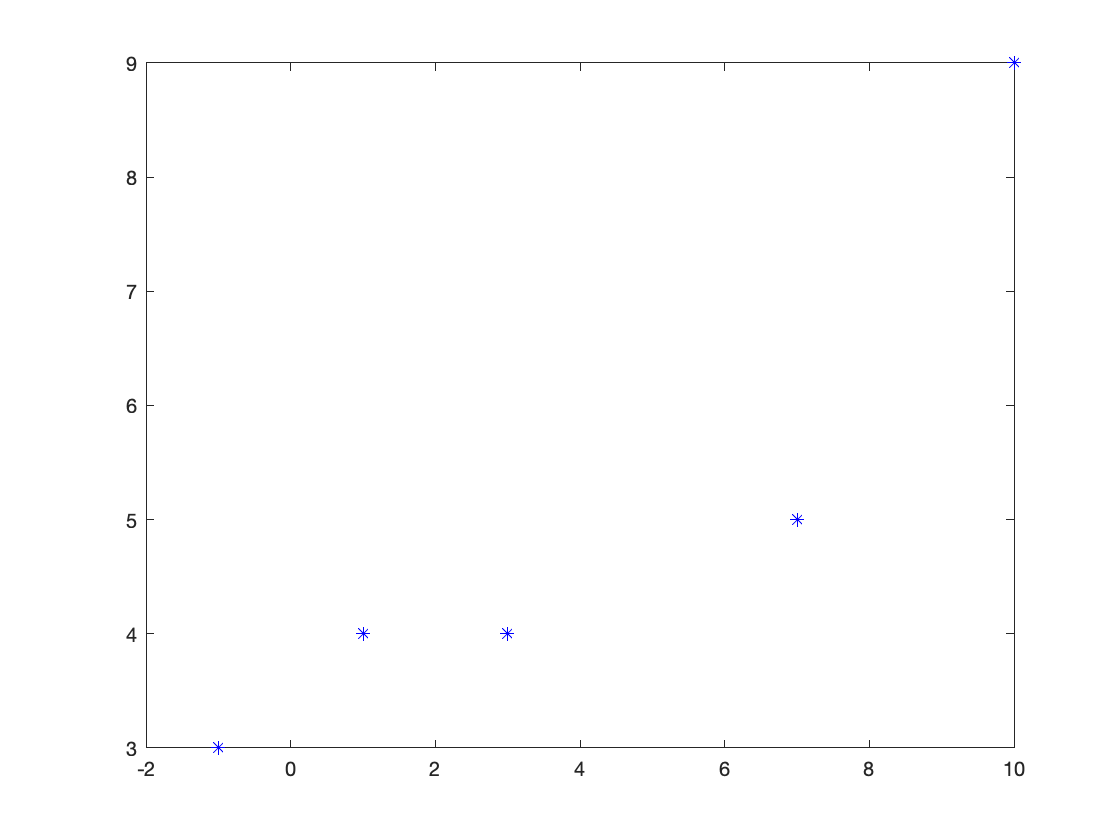

% Excercise 20.1
D = [-1 3; 1 4; 3 4; 7 5; 10 9];

figure; plot(D(:, 1), D(:, 2), "b*");

D2 = D - mean(D);

figure; hold on; 

plot(D2(:, 1), D2(:, 2), "r*");
D_cov = D2' * D2;
[V, D] = eig(D_cov);
quiver(0, 0, V(1, 1), V(2, 1));
quiver(0, 0, V(1, 2), V(2, 2));

projection = D2 * V(:, 2)

projection =     5.3684
    3.1323
    1.3398
   -2.6889
   -7.1516


B = projection * V(:, 2)'

B =    -4.8116   -2.3807
   -2.8075   -1.3891
   -1.2008   -0.5941
    2.4100    1.1924
    6.4099    3.1715


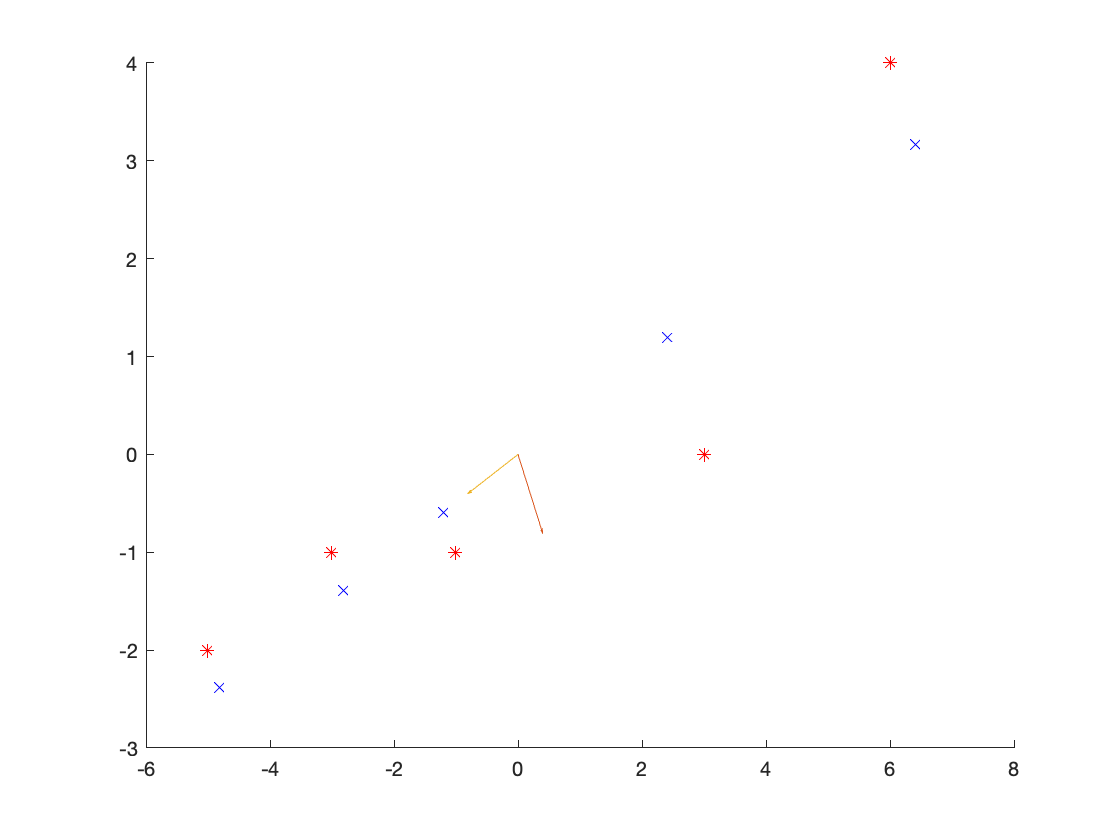


plot(B(:, 1), B(:, 2), 'xb')

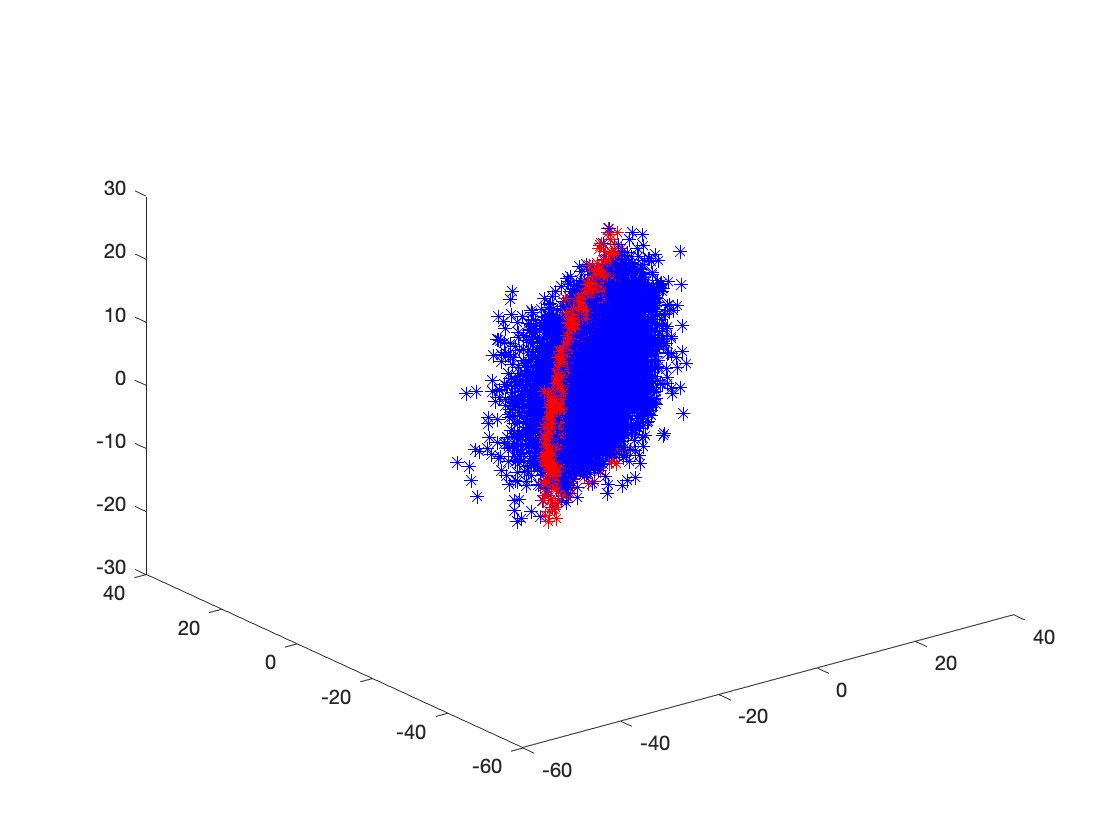

% Excercise 20.3
load("avg_temperatures_pt2.mat");
D = [b_tr w_tr s_tr];
R = D' * D;

[V, M] = eig(R);
Vp = V(:, 2:3);
V1 = Vp(:, 1);
V2 = Vp(:, 2);

Vmagic = [V1'; V2'];

T = [b_tr' - mean(b_tr); w_tr' - mean(w_tr); s_tr' - mean(s_tr)];

alpha = Vmagic * T;

T_hat = Vmagic' * alpha;

hold on; clf;
plot3(T(1, :), T(2, :), T(3, :), "b*"); hold on;
plot3(T_hat(1, :), T_hat(2, :), T_hat(3, :), "r*");

### Faces

  Name                  Size                   Bytes  Class      Attributes

  grayfaces_test       64x64x356            11665408  double               
  smile_test          356x1                      356  logical              
  subject_test        356x1                     2848  double               



Initial Training Sample Face:


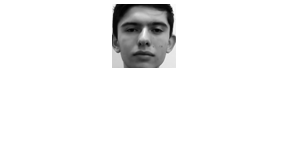

Pre-Compressed Mean-Adjusted Reshaped Training Sample Face:


Decompressed Training Face Sample:


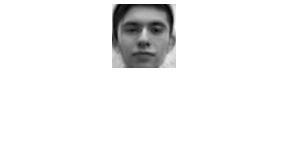

test_faces_in_facespace = 	1.0e+03 *

   -0.7902   -0.9978   -0.6244    0.3187   -0.8285    0.9024   -0.6078   -0.2267    0.7924    0.2674    0.1699    0.1332    0.0698   -0.4228   -0.3310    0.1317    0.2338   -0.1719    0.1329    0.3468    0.4373   -0.2687    0.1610   -0.3753   -0.1927    0.0957   -0.5926   -0.3875    0.1091   -0.0795   -0.4744    0.1805   -0.1664   -0.2838    0.2451   -0.0121   -0.0592   -0.0065   -0.1860   -0.1548    0.2427   -0.0954   -0.1680    0.0449    0.1115   -0.0899   -0.2858    0.0915   -0.3072   -0.1831
   -0.5061   -0.8324   -0.0959    0.2594   -0.6006    0.8093   -0.4340   -0.2784    0.7888    0.3357   -0.0160   -0.0742    0.1464   -0.5235   -0.3279    0.1759    0.2698   -0.2585    0.1426    0.5902    0.3696   -0.3713    0.2988   -0.5227   -0.2952    0.0865   -0.3964   -0.2272    0.0563    0.0722   -0.5220    0.1444   -0.1815   -0.4772    0.2420    0.1137   -0.0818   -0.0899   -0.1403   -0.1913    0.1684   -0.0648   -0.3576    0.1184    0.2340   -0.0206 

nearest_neighbors =      3
     4
     7
     8
    11
    12
    15
    16
    19
    20



n =

     []



foo =      1     1     1     1     2     2     2     2     3     3     3     3     4     4     4     4     5     5     5     5     6     6     6     6     7     7     7     7     8     8     8     8     9     9     9     9    10    10    10    10    11    11    11    11    12    12    12    12    13    13


bar =      1
     1
     1
     1
     2
     2
     2
     2
     3
     3


ans =      1     1
     1     1
     1     1
     1     1
     2     2
     2     2
     2     2
     2     2
     3     3
     3     3
